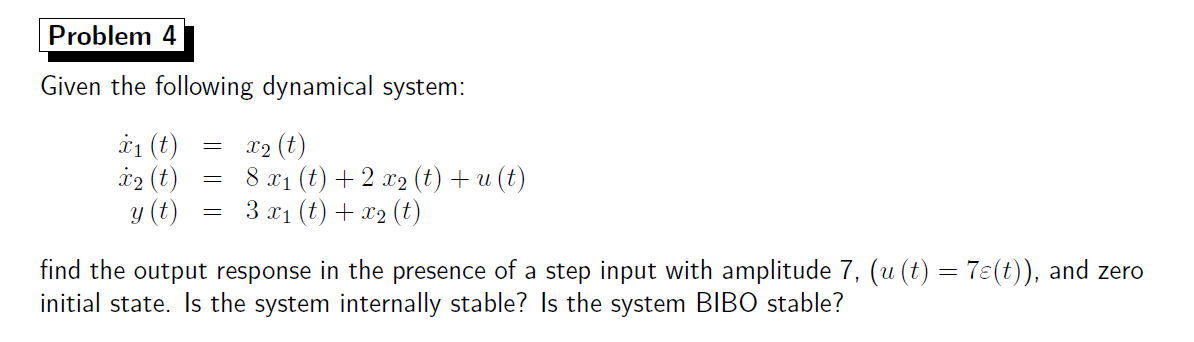

A=[0 1;8 2];
B=[0 1]';
C=[3 1];
D=[0];

sys=ss(A,B,C,D);
s=tf('s');
H=tf(sys)

H =
 
      s + 3
  -------------
  s^2 - 2 s - 8
 
Continuous-time transfer function.



x0=0

x0 = 0

U=7/s;
Y=minreal(zpk(C*inv(s*eye(2)-A)*(B*U+x0)+D*U),1e-3)

Y =
 
     7 (s+3)
  -------------
  s (s-4) (s+2)
 
Continuous-time zero/pole/gain model.



[numY,denY]=tfdata(Y,'v')  %v because I need a vectorial format

numY =          0         0    7.0000   21.0000


denY =     1.0000   -2.0000   -8.0000         0



[r,p]=residue(numY,denY) %the residues are the numerators and p are the poles

r =     2.0417
    0.5833
   -2.6250


p =     4.0000
   -2.0000
         0




pole(H)

ans =      4
    -2


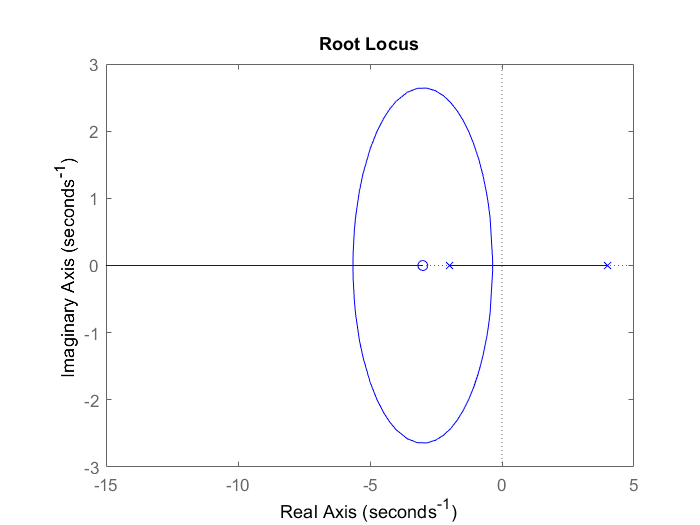

rlocus(H(1),'b')

There is a positive eigenvalue so the system is unstable and divergent.

## **SYMBOLIC METHOD**

clear
syms t f H s

H=(s+3)/((s-4)*(s+2))

$$H = \frac{s+3}{\left(s+2\right)\,\left(s-4\right)}$$

f=piecewise(t<0, 0,t>=0,7)

$$f = \left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ 7 & \text{ if }0\leq t \end{array}\right.$$

y=vpa(simplify(ilaplace(laplace(f)*H)),4)

$$y = 0.5833\,{\mathrm{e}}^{-2.0\,t}+2.042\,{\mathrm{e}}^{4.0\,t}-2.625$$

% fplot(X)
